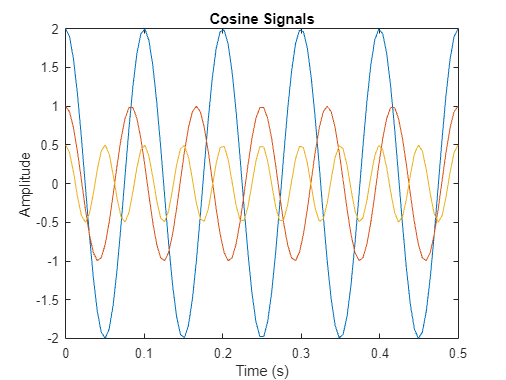


% Problem 1: Sampling and frequency-domain aliasing

x = 256;
a = 1 + mod(x, 3);

% Question 1:
% Generate time vector
t = linspace(0,1/a);  

% Generate the cosine signal
y1 = a*cos(2*pi*(5*a)*t);
y2 = (a/2)*cos(2*pi*(6*a)*t);
y3 = (a/4)*cos(2*pi*(10*a)*t);

% Plot the cosine signals
plot(t, y1);
hold on;
plot(t, y2);
hold on;
plot(t, y3);
hold off
xlabel('Time (s)');
ylabel('Amplitude');
title('Cosine Signals');

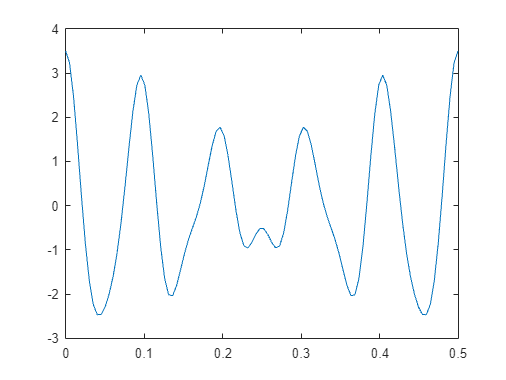

%2
y=y1+y2+y3;
plot(t,y)

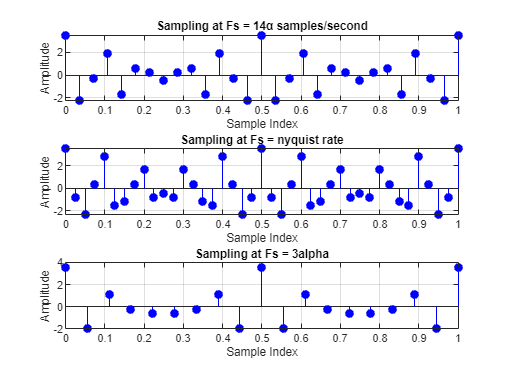

%3rd
alpha =2;
duration = 1/alpha;
t = [0:0.0001:1/alpha];

cumulative_waveform = alpha * cos(2 * pi * 5 * alpha * t) + ...
    (alpha/2) * cos(2 * pi * 6 * alpha * t) + ...
    (alpha/4) * cos(2 * pi * 10 * alpha * t);

Fs_a = 14 * alpha;
Fs_b = 2 * 10 * alpha;  % Nyquist rate
Fs_c = 9 * alpha;       % Aliasing rate

n_a = 0:1/Fs_a:1;
n_b = 0:1/Fs_b:1;
n_c = 0:1/Fs_c:1;

sampled_waveform_a = alpha * cos(2 * pi * 5 * alpha * n_a) + ...
    (alpha/2) * cos(2 * pi * 6 * alpha * n_a) + ...
    (alpha/4) * cos(2 * pi * 10 * alpha * n_a);

sampled_waveform_b = alpha * cos(2 * pi * 5 * alpha * n_b) + ...
    (alpha/2) * cos(2 * pi * 6 * alpha * n_b) + ...
    (alpha/4) * cos(2 * pi * 10 * alpha * n_b);

sampled_waveform_c = alpha * cos(2 * pi * 5 * alpha * n_c) + ...
    (alpha/2) * cos(2 * pi * 6 * alpha * n_c) + ...
    (alpha/4) * cos(2 * pi * 10 * alpha * n_c);

figure;

subplot(3, 1, 1);
stem(n_a, sampled_waveform_a, 'b', 'filled');
xlabel('Sample Index');
ylabel('Amplitude');
title('Sampling at Fs = 14α samples/second');
grid on;

subplot(3, 1, 2);
stem(n_b, sampled_waveform_b, 'b', 'filled');
xlabel('Sample Index');
ylabel('Amplitude');
title('Sampling at Fs = nyquist rate');
grid on;

subplot(3, 1, 3);
stem(n_c, sampled_waveform_c, 'b', 'filled');
xlabel('Sample Index');
ylabel('Amplitude');
title('Sampling at Fs = 3alpha');
grid on;

%4
alpha =2

alpha = 2

freq_1 = 5 * alpha

freq_1 = 10

freq_2 = 6 * alpha

freq_2 = 12

freq_3 = 10 * alpha

freq_3 = 20


%sampling frequencies
Fs_a = 14 * alpha; % Fs = 14alpha samples/second
Fs_nyquist = 2 * max([freq_1, freq_2, freq_3]); % Nyquist rate
Fs_aliasing = 9 * alpha; % Aliasing scenario

signal_1 = alpha * cos(2 * pi * freq_1 * t);
signal_2 = (alpha / 2) * cos(2 * pi * freq_2 * t);
signal_3 = (alpha / 4) * cos(2 * pi * freq_3 * t);
signal_4 = signal_1 + signal_2 + signal_3;


% Sample the cumulative signal at different sampling frequencies
samples_a = signal_4(1 : round(Fs_a * duration) : end)

samples_a =     3.5000    3.4790    3.4163    3.3130    3.1709    2.9923    2.7803    2.5383    2.2703    1.9807    1.6739    1.3546    1.0277    0.6977    0.3693    0.0467   -0.2661   -0.5655   -0.8483   -1.1119   -1.3541   -1.5733   -1.7685   -1.9391   -2.0849   -2.2064   -2.3043   -2.3796   -2.4337   -2.4681   -2.4844   -2.4843   -2.4694   -2.4413   -2.4015   -2.3510   -2.2909   -2.2220   -2.1447   -2.0593   -1.9658   -1.8639   -1.7532   -1.6332   -1.5033   -1.3628   -1.2112   -1.0480   -0.8728   -0.6857


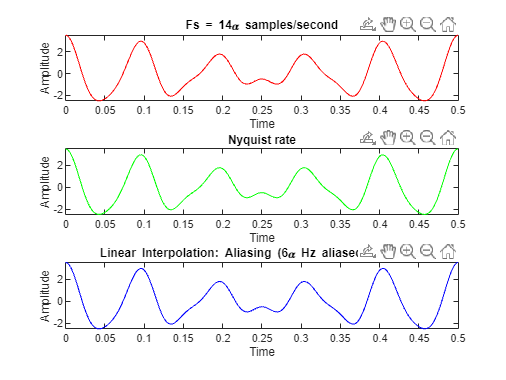

samples_nyquist = signal_4(1 : round(Fs_nyquist * duration) : end);
samples_aliasing = signal_4(1 : round(Fs_aliasing * duration) : end);

% Discrete-time waveforms using stem
time_a = linspace(0, duration, length(samples_a));
time_nyquist = linspace(0, duration, length(samples_nyquist));
time_aliasing = linspace(0, duration, length(samples_aliasing));

% Plot interpolated signals
figure;

subplot(3, 1, 1);
plot(time_a, samples_a, 'r');
title('Fs = 14\alpha samples/second');
xlabel('Time');
ylabel('Amplitude');


subplot(3, 1, 2);
plot(time_nyquist, samples_nyquist, 'g');
title('Nyquist rate');
xlabel('Time');
ylabel('Amplitude');


subplot(3, 1, 3);
plot(time_aliasing, samples_aliasing, 'b');
title('Linear Interpolation: Aliasing (6\alpha Hz aliased to 3\alpha Hz)');
xlabel('Time');
ylabel('Amplitude');

% (3)
subplot(3,1,1)
Fs1=14*a

Fs1 = 35.4872

t1=0:1/Fs1:1/a

t1 =          0    0.0282    0.0564    0.0845    0.1127    0.1409    0.1691    0.1973    0.2254    0.2536    0.2818    0.3100    0.3382    0.3663    0.3945


yo=a.*cos(2*pi*5*a*t1)+(a./2).*cos(2*pi*6*a*t1)+(a./4).*cos(2*pi*10*a*t1)

yo =     4.4359   -2.8633   -0.3448    2.3969   -2.1707    0.7833    0.2975   -0.6337    0.2975    0.7833   -2.1707    2.3969   -0.3448   -2.8633    4.4359


% stem(t1,yo)
% plot(t1,yo)

subplot(3,1,2)
Fs2=2*10*a

Fs2 = 50.6960

t2=0:1/Fs2:1/a

t2 =          0    0.0197    0.0395    0.0592    0.0789    0.0986    0.1184    0.1381    0.1578    0.1775    0.1973    0.2170    0.2367    0.2564    0.2762    0.2959    0.3156    0.3353    0.3551    0.3748    0.3945


yo2=a.*cos(2*pi*5*a*t2)+(a./2).*cos(2*pi*6*a*t2)+(a./4).*cos(2*pi*10*a*t2)

yo2 =     4.4359   -1.0253   -2.9264    0.3916    3.5601   -1.9011   -1.5095    0.3916    2.1432   -1.0253   -0.6337   -1.0253    2.1432    0.3916   -1.5095   -1.9011    3.5601    0.3916   -2.9264   -1.0253    4.4359


% stem(t2,yo2)
% plot(t2,yo2)


subplot(3,1,3)
Fs3=9*a

Fs3 = 22.8132

t3=0:1/Fs3:1/a

t3 =          0    0.0438    0.0877    0.1315    0.1753    0.2192    0.2630    0.3068    0.3507    0.3945


yo3=a.*cos(2*pi*5*a*t3)+(a./2).*cos(2*pi*6*a*t3)+(a./4).*cos(2*pi*10*a*t3)

yo3 =     4.4359   -2.5302    1.4181   -0.3169   -0.7890   -0.7890   -0.3168    1.4181   -2.5302    4.4359


% stem(t3,yo3)
% plot(t3,yo3)


subplot(3,1,1)
x=fft(yo)

x =    4.4359 + 0.0000i   4.4845 + 0.9532i   4.6627 + 2.0760i   5.1456 + 3.7385i   7.8446 + 8.7123i   9.1353 +15.8228i   0.2578 + 0.7934i  -0.4791 - 4.5580i  -0.4791 + 4.5580i   0.2578 - 0.7934i   9.1353 -15.8228i   7.8446 - 8.7123i   5.1456 - 3.7385i   4.6627 - 2.0760i   4.4845 - 0.9532i


fx=linspace(0,Fs1,length(x))

fx =          0    2.5348    5.0696    7.6044   10.1392   12.6740   15.2088   17.7436   20.2784   22.8132   25.3480   27.8828   30.4176   32.9524   35.4872


plot(fx,abs(x).^2)
ylabel('amplitude')
xlabel('frequency')


subplot(3,1,2)
y=fft(yo2)

y =    4.4359 + 0.0000i   4.5102 + 0.6798i   4.7695 + 1.4712i   5.3780 + 2.5899i   7.0497 + 4.8064i  21.1840 +19.6559i   3.6617 + 4.5917i  -2.8054 - 4.8591i  -0.3501 - 0.8919i   0.3556 + 1.5581i   0.6058 + 8.0832i   0.6058 - 8.0832i   0.3556 - 1.5581i  -0.3501 + 0.8919i  -2.8054 + 4.8591i   3.6617 - 4.5917i  21.1840 -19.6559i   7.0497 - 4.8064i   5.3780 - 2.5899i   4.7695 - 1.4712i   4.5102 - 0.6798i


fy=linspace(0,Fs2,length(y))

fy =          0    2.5348    5.0696    7.6044   10.1392   12.6740   15.2088   17.7436   20.2784   22.8132   25.3480   27.8828   30.4176   32.9524   35.4872   38.0220   40.5568   43.0916   45.6264   48.1612   50.6960


plot(fy,abs(y).^2)
ylabel('amplitude')
xlabel('frequency')

subplot(3,1,3)
z=fft(yo3)

z =    4.4359 + 0.0000i   6.9774 + 2.2671i   3.9028 + 2.8355i   6.0849 + 8.3752i   2.9965 + 9.2221i   0.0000 + 0.0000i   2.9965 - 9.2221i   6.0849 - 8.3752i   3.9028 - 2.8355i   6.9774 - 2.2671i


fz=linspace(0,Fs3,length(z))

fz =          0    2.5348    5.0696    7.6044   10.1392   12.6740   15.2088   17.7436   20.2784   22.8132


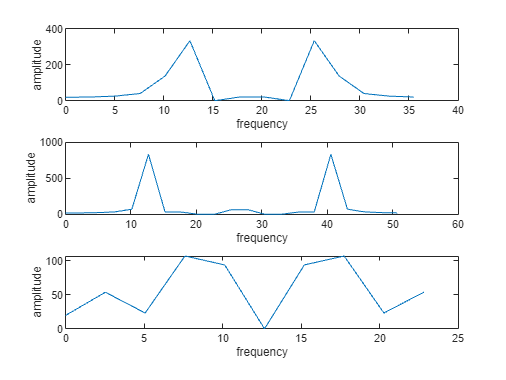

plot(fz,abs(z).^2)
ylabel('amplitude')
xlabel('frequency')

%Problem 2
notes=["Do" "Re" "Mi" "Fa" "So" "La" "Ti" "Do"];
freq=[261.6 293.6 329.6 349.2 392.0 440.0 493.8 523.25];

a=[];
for n=1:8
   t=0:0.000125:1; % Note duration
   a=[a sin(2*pi*freq(n)*t)]; % Signal
end

duration=10;
fs=[15000,20000,30000,40000,44100,50000];
for n=1:length(fs)
    sound(a,fs(n));
    pause(duration);
end    

% Saving as .wav file
Fs=44100;
filename="DoReMi.wav";
audiowrite(filename,a,Fs);